Clear Workspace and set directory

clear;
clc;
cd '/Users/naveen/Desktop/Class_work/EE502/EEG and Empatica E4 Signals - Five Minute P300 Test and FAS Scores/EEG'

Load the raw data

eeg_data = cell(1, 14);
eeg_spec_data = cell(1,14);
N = zeros(1,14);
T = zeros(1,14);
f0 = zeros(1,14);
Fs = 250;

for h = 1:1:14                                   % Get session 1 through 9 for participant
    g = "S" + h +".mat" ;          % Make a csv file input name
    load_data = load(g);
    eeg_data{1, h} = load_data.Samples();            % Create a cell for each session
    eeg_spec_data{1, h} = fft(eeg_data{1, h});  % Spectrum data for EEG
    N(1, h) = length(eeg_data{1, h});           % number of samples per channel
    T(1, h) = N(1, h)/Fs;                       % The time axis for all data
    f0(1, h) = Fs/N(1, h);                      % frequency per sample
    clearvars load_data, g;
end

Apply notch filter

cb = 0.2/(Fs/2);
ca = 60/(Fs/2);
[b,a] = butter(4,[cb,ca]);
clearvars cb ca

Filter the EEG data using butterworth filter and convert to frequency domain

eeg_filtered = cell(1, 14);
eeg_spec_filtered = cell(1, 14);


for h = 1:1:14
    eeg_filtered{1, h} = filtfilt(b,a,eeg_data{1, h});    % Application of Butterworth filter
    eeg_spec_filtered{1, h} = fft(eeg_filtered{1, h});    % Convert to frequency domain
end


clearvars a b h

Plot raw vs filtered data

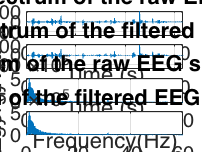

ft = 1/Fs;
t = [ft:ft:T(1, 1)];                                % Create the time axis

figure(1)
subplot(4,1,1)

plot(t, eeg_data{1, 1}(:, 1)/10)
title('Time spectrum of the raw EEG signal')
xlabel('Time (s)'),ylabel('Amplitude (\muV)'),grid on

subplot(4,1,2)
plot(t, eeg_filtered{1, 1}(:, 1)/10)
title('Time spectrum of the filtered EEG signal')
xlabel('Time (s)'),ylabel('Amplitude (\muV)'),grid on

subplot(4,1,3)
plot(f0(1, 1)*(0:N(1, 1)-1),abs(eeg_spec_data{1, 1}(:, 1)))
title('Frequency spectrum of the raw EEG signal (0.1Hz a 60Hz)')
xlabel('Frequency(Hz)'),ylabel('Energy (\muV)'),grid on
xlim([0 60]);

subplot(4,1,4)
plot(f0(1, 1)*(0:N(1, 1)-1),abs(eeg_spec_filtered{1, 1}(:, 1)))
title('Frequency spectrum of the filtered EEG signal (0.1Hz a 60Hz)')
xlabel('Frequency(Hz)'),ylabel('Energy (\muV)'),grid on
xlim([0 60]);


clearvars eeg_data eeg_spec_data

Create frequency band filters

hp = 0.2/(Fs/2);                % High-pass frequency
lp = 4/(Fs/2);                  % Low-pass frequency
[db,da] = butter(2,[hp, lp]);   % Delta band filter

hp = 4/(Fs/2);                  % High-pass frequency
lp = 8/(Fs/2);                  % Low-pass frequency
[tb,ta] = butter(4,[hp, lp]);   % Theta band filter

hp = 8/(Fs/2);                  % High-pass frequency
lp = 12/(Fs/2);                 % Low-pass frequency
[ab,aa] = butter(4,[hp, lp]);   % Alpha band filter

hp = 12/(Fs/2);                 % High-pass frequency
lp = 26/(Fs/2);                 % Low-pass frequency
[bb,ba] = butter(4,[hp, lp]);   % Beta band filter

hp = 26/(Fs/2);                 % High-pass frequency
lp = 100/(Fs/2);                 % Low-pass frequency
[gb,ga] = butter(4,[hp, lp]);   % Gamma band filter

clearvars lp hp

Apply filters to get the bands

eeg_delta = cell(1, 14);
eeg_theta = cell(1, 14);
eeg_alpha = cell(1, 14);
eeg_beta = cell(1, 14);
eeg_gamma = cell(1, 14);

for h = 1:1:14
    eeg_delta{1, h} = filtfilt(db,da,eeg_filtered{1, h});  % Extract delta band
    eeg_theta{1, h} = filtfilt(tb,ta,eeg_filtered{1, h});  % Extract theta band
    eeg_alpha{1, h} = filtfilt(ab,aa,eeg_filtered{1, h});  % Extract alpha band
    eeg_beta{1, h}  = filtfilt(bb,ba,eeg_filtered{1, h});  % Extract beta band
    eeg_gamma{1, h} = filtfilt(gb,ga,eeg_filtered{1, h});  % Extract gamma band
end

clearvars h db da ta tb aa ab bb ba ga gb

Plot each band

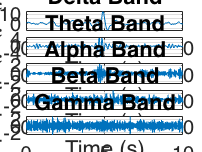

figure(2)

subplot(5,1,1)
plot(t, eeg_delta{1, 1}(:, 1)/10)
title('Delta Band')
xlabel('Time (s)'),ylabel('Amplitude (\muV)'),grid on
xlim([0 10]);

subplot(5,1,2)
plot(t, eeg_theta{1, 1}(:, 1)/10)
title('Theta Band')
xlabel('Time (s)'),ylabel('Amplitude (\muV)'),grid on
xlim([0 10]);

subplot(5,1,3)
plot(t, eeg_alpha{1, 1}(:, 1)/10)
title('Alpha Band')
xlabel('Time (s)'),ylabel('Amplitude (\muV)'),grid on
xlim([0 10]);

subplot(5,1,4)
plot(t, eeg_beta{1, 1}(:, 1)/10)
title('Beta Band')
xlabel('Time (s)'),ylabel('Amplitude (\muV)'),grid on
xlim([0 10]);

subplot(5,1,5)
plot(t, eeg_gamma{1, 1}(:, 1)/10)
title('Gamma Band')
xlabel('Time (s)'),ylabel('Amplitude (\muV)'),grid on
xlim([0 10]);

Apply FFT on each band

eeg_spec_delta = cell(1, 14);
eeg_spec_theta = cell(1, 14);
eeg_spec_alpha = cell(1, 14);
eeg_spec_beta = cell(1, 14);
eeg_spec_gamma = cell(1, 14);

for h = 1:1:14
    eeg_spec_delta{1, h} = fft(eeg_delta{1, h});       % Spectral delta band
    eeg_spec_theta{1, h} = fft(eeg_theta{1, h});       % Spectral theta band
    eeg_spec_alpha{1, h} = fft(eeg_alpha{1, h});       % Spectral alpha band
    eeg_spec_beta{1, h} = fft(eeg_beta{1, h});         % Spectral beta band
    eeg_spec_gamma{1, h} = fft(eeg_gamma{1, h});       % Spectral gamma band
end

clearvars h

Plot frequecny spectrum of each data

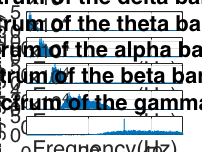

%% Plot spectral data of each band

figure(3)

subplot(5,1,1)
plot(f0(1, 1)*(0:N(1, 1)-1),abs(eeg_spec_delta{1, 1}(:, 1)))
title('Frequency spectrum of the delta band (0.1Hz a 50Hz)')
xlabel('Frequency(Hz)'),ylabel('Energy (\muV)'),grid on
xlim([0 50]);

subplot(5,1,2)
plot(f0(1, 1)*(0:N(1, 1)-1),abs(eeg_spec_theta{1, 1}(:, 1)))
title('Frequency spectrum of the theta band (0.1Hz a 50Hz)')
xlabel('Frequency(Hz)'),ylabel('Energy (\muV)'),grid on
xlim([0 50]);

subplot(5,1,3)
plot(f0(1, 1)*(0:N(1, 1)-1),abs(eeg_spec_alpha{1, 1}(:, 1)))
title('Frequency spectrum of the alpha band (0.1Hz a 50Hz)')
xlabel('Frequency(Hz)'),ylabel('Energy (\muV)'),grid on
xlim([0 50]);

subplot(5,1,4)
plot(f0(1, 1)*(0:N(1, 1)-1),abs(eeg_spec_beta{1, 1}(:, 1)))
title('Frequency spectrum of the beta band (0.1Hz a 50Hz)')
xlabel('Frequency(Hz)'),ylabel('Energy (\muV)'),grid on
xlim([0 50]);

subplot(5,1,5)
plot(f0(1, 1)*(0:N(1, 1)-1),abs(eeg_spec_gamma{1, 1}(:, 1)))
title('Frequency spectrum of the gamma (0.1Hz a 50Hz)')
xlabel('Frequency(Hz)'),ylabel('Energy (\muV)'),grid on
xlim([0 50]);


clearvars f0 ft T t

Windowing

%% Windowing

w_size = Fs * 0.5;          % The number of samples per 5s segment
overlap = w_size/2;  

n_win =floor(N/125 - 1);    % Number of windows per channel

clearvars Fs N

Extract features

eeg_avg = cell(1, 14);
eeg_std = cell(1, 14);
eeg_mav = cell(1, 14);
eeg_rms = cell(1, 14);
eeg_skw = cell(1, 14);
eeg_kur = cell(1, 14);
eeg_hac = cell(1, 14);
eeg_hmb = cell(1, 14);
eeg_hcp = cell(1, 14);
eeg_she = cell(1, 14);
eeg_spe = cell(1, 14);
eeg_psd = cell(1, 14);

for h=1:1:14   
    eeg_avg{1, h} = zeros(n_win(1, h),8); % Average
    eeg_std{1, h} = zeros(n_win(1, h),8); % Standard Deviation
    eeg_mav{1, h} = zeros(n_win(1, h),8); % Mean Absolute Value
    eeg_rms{1, h} = zeros(n_win(1, h),8); % Root Mean Square
    eeg_skw{1, h} = zeros(n_win(1, h),8); % Skewness
    eeg_kur{1, h} = zeros(n_win(1, h),8); % Kurtosis
    eeg_hac{1, h} = zeros(n_win(1, h),8); % Hjorth Activity
    eeg_hmb{1, h} = zeros(n_win(1, h),8); % Hjorth Mobility
    eeg_hcp{1, h} = zeros(n_win(1, h),8); % Hjorth Complexity
    eeg_she{1, h} = zeros(n_win(1, h),8); % Shannon's EntropyW
    eeg_spe{1, h} = zeros(n_win(1, h),8); % Spectral Entropy
    eeg_psd{1, h} = zeros(n_win(1, h),8); % Power Spectral Density
end 

for h = 1:1:14
    w_start = 1;                % Start at the first sample
    w_end = w_size;             % End at window length
    for n = 1:1:n_win(1, h)
        eeg_avg{1, h}(n, :) = mean(eeg_filtered{1, h}(w_start:w_end, :));                       % Average for window
        eeg_std{1, h}(n, :) = std(eeg_filtered{1, h}(w_start:w_end, :));                        % Standard Deviation for window
        eeg_mav{1, h}(n, :) = mean(abs(eeg_filtered{1, h}(w_start:w_end, :)));                  % Mean Absolute Value for window
        eeg_rms{1, h}(n, :) = rms(eeg_filtered{1, h}(w_start:w_end, :));                        % Root Mean Square for window
        eeg_skw{1, h}(n, :) = skewness(eeg_filtered{1, h}(w_start:w_end, :));                   % Skewness for window
        eeg_kur{1, h}(n, :) = kurtosis(eeg_filtered{1, h}(w_start:w_end, :));                   % Kurtosis for window
        eeg_hac{1, h}(n, :) = var(eeg_filtered{1, h}(w_start:w_end, :));                        % Hjorth Activity for window
        eeg_she{1, h}(n, :) = wentropy(eeg_filtered{1, h}(w_start:w_end, :), 'shannon');        % Shannon's Entropy for window
        eeg_spe{1, h}(n, :) = wentropy(eeg_spec_filtered{1, h}(w_start:w_end, :), 'shannon');   % Spectral Entropy for window
        eeg_psd{1, h}(n, :) = mean(pburg(eeg_filtered{1, h}(w_start:w_end, :), 4));             % Power Spectral Density for window
        w_start = w_start + overlap;        % Shift the start of the next window forward by 50%
        w_end = w_start + w_size;  
    end
end

feats = {eeg_avg, eeg_std, eeg_mav, eeg_rms, eeg_skw, eeg_kur, ...
    eeg_she, eeg_spe, eeg_psd};

clearvars h n eeg_avg eeg_std eeg_mav eeg_rms eeg_skw eeg_kur eeg_hac ...
    eeg_hmb eeg_hcp eeg_she eeg_spe eeg_psd eeg_filtered eeg_spec_filtered

Export the features into csv file

%% Export features for overall EEG data
p = 1
table_names = ["Participant", "Feature", "ch1", "ch2", "ch3", "ch4", "ch5", ...
    "ch6",  "ch7", "ch8"];

var_types = ["double", "string", "double", "double", "double", "double", "double",... 
    "double", "double", "double"];

labels = ["Mean", "Standard Deviation", "Mean Absolute Value", ...
    "Root Mean Square", "Skewness", "Kurtosis", ...
    "Shannon's Entropy", ...
    "Spectral Entropy", "Power Spectral Density"];

for h = 1:1:14
    eeg_features{1, h} = table('Size', [n_win(1, h)*9 ,10], ...
        'VariableTypes', var_types);                                                % Create table to store all features
    allVars = 1:width(eeg_features{1, h});
    eeg_features{1, h} = renamevars(eeg_features{1, h}, allVars, table_names);      % Column names
    eeg_features{1, h}(:, 1) = {p};

    for n = 1:1:9
        eeg_features{1, h}(n_win(1, h)*(n-1)+1:n_win(1, h)*n, 2) = {labels(1, n)};  % Label features on table
        feat = array2table(real(feats{1, n}{1, h}));
        eeg_features{1, h}(n_win(1, h)*(n-1)+1:n_win(1, h)*n, 3:10) = feat;         % Label features on table
    end
    g = "Features_S" + h +".csv";                                        % Make a csv file output name
    writetable(eeg_features{1, h}, g);
end 

clearvars h allVars eeg_features feat feats n g